%% SCRIPT 1: CARGAR DATOS NREL-118
clear; clc;

fprintf('=== CARGANDO DATOS NREL-118 ===\n\n');

=== CARGANDO DATOS NREL-118 ===




% Rutas
ruta_RT = 'C:\Users\marce\Downloads\input-files\RT\Wind\';
ruta_DA = 'C:\Users\marce\Downloads\input-files\DA\Wind\';

% Inicializar
n_generadores = 17;
data_temp = readtable([ruta_RT 'Wind1RT.csv']);
n_obs_total = height(data_temp);

potencias_reales = zeros(n_obs_total, n_generadores);
pronosticos = zeros(n_obs_total, n_generadores);

% Cargar 17 generadores
fprintf('Cargando 17 generadores...\n');

Cargando 17 generadores...


for gen = 1:n_generadores
    data_RT = readtable([ruta_RT sprintf('Wind%dRT.csv', gen)]);
    potencias_reales(:, gen) = data_RT{:, 2};
    
    data_DA = readtable([ruta_DA sprintf('Wind%dDA.csv', gen)]);
    pronosticos(:, gen) = data_DA{:, 2};
end

% Usar 2000 observaciones
n_usar = 2000;
potencias_reales = potencias_reales(1:n_usar, :);
pronosticos = pronosticos(1:n_usar, :);

fprintf('✓ Datos cargados: %d observaciones\n\n', n_usar);

✓ Datos cargados: 2000 observaciones




% Guardar
save('datos_nrel118.mat', 'potencias_reales', 'pronosticos');

%% SCRIPT 2: CONSTRUIR MATRIZ X
clear; clc;
load('datos_nrel118.mat');

fprintf('=== CONSTRUCCIÓN DE MATRIZ X ===\n\n');

=== CONSTRUCCIÓN DE MATRIZ X ===




n_obs = size(potencias_reales, 1);
n_generadores = 17;
n_lags = 72;

% Variable objetivo: Generador 1
Y = potencias_reales(:, 1);

% Construir X
X = [];

% 1. Históricos (72 lags × 17 generadores = 1224)
for gen = 1:n_generadores
    for lag = 1:n_lags
        X_lag = [nan(lag, 1); potencias_reales(1:end-lag, gen)];
        X = [X, X_lag];
    end
end

% 2. Pronósticos (17)
X = [X, pronosticos];

% 3. Variables temporales (4)
hora = mod((1:n_obs)', 24);
dia = floor((1:n_obs)'/24);
X = [X, hora, dia, sin(2*pi*hora/24), cos(2*pi*hora/24)];

% 4. Interacciones (17)
for gen = 1:n_generadores
    X = [X, pronosticos(:,gen) .* hora];
end

fprintf('Total características: %d\n', size(X,2));

Total características: 1262



% Limpiar NaNs
idx_validos = ~any(isnan(X), 2);
X = X(idx_validos, :);
Y = Y(idx_validos);

% Normalizar
X_mean = mean(X);
X_std = std(X);
Y_mean = mean(Y);
Y_std = std(Y);

X_norm = (X - X_mean) ./ X_std;
Y_norm = (Y - Y_mean) / Y_std;

% Dividir train/validation (80%-20%)
n_train = round(0.8 * length(Y_norm));

X_train = X_norm(1:n_train, :);
Y_train = Y_norm(1:n_train);
X_val = X_norm(n_train+1:end, :);
Y_val = Y_norm(n_train+1:end);

fprintf('Train: %d | Val: %d\n\n', n_train, length(Y_val));

Train: 1542 | Val: 386




% Guardar
save('datos_matrices.mat', 'X_train', 'Y_train', 'X_val', 'Y_val', 'Y_std');

function [beta, k, tiempo] = gauss_seidel_ridge(X, Y, lambda, tol, max_iter)
    tic;
    
    n = size(X, 1);
    p = size(X, 2);
    
    % Sistema: A*beta = b
    A = X' * X + n * lambda * eye(p);
    b = X' * Y;
    
    beta = zeros(p, 1);
    
    % Iteración de Gauss-Seidel
    for k = 1:max_iter
        beta_old = beta;
        
        for i = 1:p
            suma = 0;
            for j = 1:i-1
                suma = suma + A(i,j) * beta(j);
            end
            for j = i+1:p
                suma = suma + A(i,j) * beta_old(j);
            end
            beta(i) = (b(i) - suma) / A(i,i);
        end
        
        if norm(beta - beta_old) < tol
            break;
        end
    end
    
    tiempo = toc;
end

%% OBJETIVO ESPECÍFICO 1 Y 2
clear; clc;
load('datos_matrices.mat');

fprintf('=== OBJETIVO ESPECÍFICO 1 Y 2 ===\n\n');

=== OBJETIVO ESPECÍFICO 1 Y 2 ===




% Seleccionar características por correlación
correlaciones = zeros(size(X_train, 2), 1);
for i = 1:size(X_train, 2)
    correlaciones(i) = corr(X_train(:,i), Y_train);
end
[~, idx] = sort(abs(correlaciones), 'descend');

%% EXPERIMENTO 1: Variación de p

fprintf('EXPERIMENTO 1: Variación de dimensionalidad\n\n');

EXPERIMENTO 1: Variación de dimensionalidad




p_values = [10, 20, 30, 40, 50, 60, 70, 100, 200, 500];
lambda = 1;
tol = 1e-4;
n = size(X_train, 1);

% Tabla: [p, iteraciones, tiempo, kappa, RMSE]
tabla1 = zeros(length(p_values), 5);

for i = 1:length(p_values)
    p = p_values(i);
    X_p = X_train(:, idx(1:p));
    X_val_p = X_val(:, idx(1:p));
    
    % Gauss-Seidel
    [beta, k, tiempo] = gauss_seidel_ridge(X_p, Y_train, lambda, tol, 10000);
    
    % Número de condición
    A = X_p' * X_p + n * lambda * eye(p);
    kappa = cond(A);
    
    % Error relativo en validación
    Y_pred_val = X_val_p * beta;
    err_rel = norm(Y_val - Y_pred_val) / norm(Y_val);
    
    tabla1(i, :) = [p, k, tiempo, kappa, err_rel];
    fprintf('p=%d: %d iter, %.4fs, κ=%.2e, err_rel=%.4f\n', ...
            p, k, tiempo, kappa, err_rel);
end

p=10: 20 iter, 0.0041s, κ=8.64e+00, err_rel=0.4744
p=20: 46 iter, 0.0010s, κ=1.58e+01, err_rel=0.4738
p=30: 66 iter, 0.0008s, κ=2.20e+01, err_rel=0.4827
p=40: 89 iter, 0.0012s, κ=2.85e+01, err_rel=0.4837
p=50: 113 iter, 0.0034s, κ=3.46e+01, err_rel=0.4828
p=60: 138 iter, 0.0048s, κ=4.08e+01, err_rel=0.4805
p=70: 156 iter, 0.0069s, κ=4.57e+01, err_rel=0.4795
p=100: 214 iter, 0.0164s, κ=6.07e+01, err_rel=0.4786
p=200: 253 iter, 0.0430s, κ=9.63e+01, err_rel=0.4865
p=500: 317 iter, 0.1338s, κ=1.59e+02, err_rel=0.4955



fprintf('\nTABLA 1:\n');


TABLA 1:


fprintf('  p  | Iter | Tiempo | κ(A) | Error rel\n');

  p  | Iter | Tiempo | κ(A) | Error rel


for i = 1:length(p_values)
    fprintf('%4d | %4d | %.4f | %.2e | %.4f\n', tabla1(i,:));
end

  10 |   20 | 0.0041 | 8.64e+00 | 0.4744
  20 |   46 | 0.0010 | 1.58e+01 | 0.4738
  30 |   66 | 0.0008 | 2.20e+01 | 0.4827
  40 |   89 | 0.0012 | 2.85e+01 | 0.4837
  50 |  113 | 0.0034 | 3.46e+01 | 0.4828
  60 |  138 | 0.0048 | 4.08e+01 | 0.4805
  70 |  156 | 0.0069 | 4.57e+01 | 0.4795
 100 |  214 | 0.0164 | 6.07e+01 | 0.4786
 200 |  253 | 0.0430 | 9.63e+01 | 0.4865
 500 |  317 | 0.1338 | 1.59e+02 | 0.4955



%% EXPERIMENTO 2: Variación de tolerancia

fprintf('\n\nEXPERIMENTO 2: Variación de tolerancia\n\n');



EXPERIMENTO 2: Variación de tolerancia




tolerancias = [1e-3, 1e-4, 1e-5];
p = 100;
X_p = X_train(:, idx(1:p));

% Tabla: [tol, iteraciones, tiempo]
tabla2 = zeros(length(tolerancias), 3);

for i = 1:length(tolerancias)
    tol = tolerancias(i);
    [~, k, tiempo] = gauss_seidel_ridge(X_p, Y_train, lambda, tol, 15000);
    tabla2(i, :) = [tol, k, tiempo];
    fprintf('ε=%.0e: %d iter, %.4fs\n', tol, k, tiempo);
end

ε=1e-03: 109 iter, 0.0020s
ε=1e-04: 214 iter, 0.0035s
ε=1e-05: 318 iter, 0.0053s



fprintf('\nTABLA 2:\n');


TABLA 2:


fprintf(' Tol | Iter | Tiempo\n');

 Tol | Iter | Tiempo


for i = 1:length(tolerancias)
    fprintf('%.0e | %4d | %.4f\n', tabla2(i,:));
end

1e-03 |  109 | 0.0020
1e-04 |  214 | 0.0035
1e-05 |  318 | 0.0053


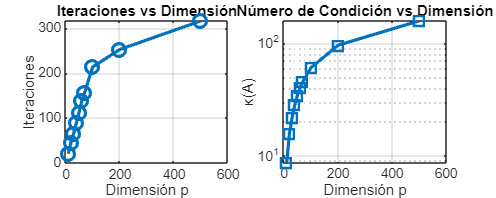


%% GRÁFICA 1: Resultados Objetivos 1 y 2

figure('Position', [100, 100, 1000, 400]);

subplot(1,2,1);
plot(p_values, tabla1(:,2), 'o-', 'LineWidth', 2, 'MarkerSize', 8);
xlabel('Dimensión p');
ylabel('Iteraciones');
title('Iteraciones vs Dimensión');
grid on;

subplot(1,2,2);
semilogy(p_values, tabla1(:,4), 's-', 'LineWidth', 2, 'MarkerSize', 8);
xlabel('Dimensión p');
ylabel('κ(A)');
title('Número de Condición vs Dimensión');
grid on;


fprintf('\n✓ Figura guardada: figura1_obj1y2.png\n');


✓ Figura guardada: figura1_obj1y2.png


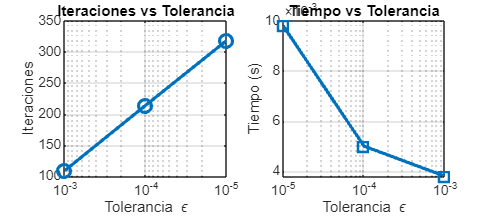


% Datos del experimento 2 (tolerancias)
tolerancias = [1e-3, 1e-4, 1e-5];
iters       = [109, 214, 318];
tiempos     = [0.0038, 0.0050, 0.0098];

figure('Position',[100 100 800 350]);

% --- Subplot 1: Iteraciones vs tolerancia ---
subplot(1,2,1);
semilogx(tolerancias, iters, 'o-', 'LineWidth', 2, 'MarkerSize', 8);
xlabel('Tolerancia \epsilon');
ylabel('Iteraciones');
title('Iteraciones vs Tolerancia');
grid on;
set(gca,'XDir','reverse');  % opcional: para que 1e-3 quede a la izquierda

% --- Subplot 2: Tiempo vs tolerancia ---
subplot(1,2,2);
semilogx(tolerancias, tiempos, 's-', 'LineWidth', 2, 'MarkerSize', 8);
xlabel('Tolerancia \epsilon');
ylabel('Tiempo (s)');
title('Tiempo vs Tolerancia');
grid on;

%% OBJETIVO ESPECÍFICO 3: BISECCIÓN (con dos puntos λ1, λ2)
clear; clc;
load('datos_matrices.mat');

fprintf('=== OBJETIVO ESPECÍFICO 3: BISECCIÓN ===\n\n');

=== OBJETIVO ESPECÍFICO 3: BISECCIÓN ===




% Seleccionar características
correlaciones = zeros(size(X_train, 2), 1);
for i = 1:size(X_train, 2)
    correlaciones(i) = corr(X_train(:,i), Y_train);
end
[~, idx] = sort(abs(correlaciones), 'descend');

p = 100;
X_p     = X_train(:, idx(1:p));
X_val_p = X_val(:,   idx(1:p));

% Parámetros de la búsqueda
lambda_min  = 1e-4;
lambda_max  = 1e2;
tol_bisec   = 0.1;    % criterio |λmax - λmin| < tol_bisec
tol_GS      = 1e-4;
max_iterGS  = 5000;

lambdas_eval  = [];
errores_eval  = [];

fprintf('Bisección en [%.0e, %.0e]:\n', lambda_min, lambda_max);

Bisección en [1e-04, 1e+02]:



% Función de error en validación (puedes usar RMSE o error relativo)
error_val = @(lambda) ...
    calcular_error_validacion(X_p, Y_train, X_val_p, Y_val, lambda, tol_GS, max_iterGS);

while (lambda_max - lambda_min) > tol_bisec

    % Dos puntos internos dentro del intervalo
    lambda1 = lambda_min + (lambda_max - lambda_min)/3;
    lambda2 = lambda_max - (lambda_max - lambda_min)/3;

    err1 = error_val(lambda1);
    err2 = error_val(lambda2);

    lambdas_eval = [lambdas_eval; lambda1; lambda2];
    errores_eval = [errores_eval; err1; err2];

    fprintf('  λ1=%.4f, err1=%.4f | λ2=%.4f, err2=%.4f\n', lambda1, err1, lambda2, err2);

    % Actualizar el intervalo según comparación de f(λ1) y f(λ2)
    if err1 < err2
        % El mínimo está entre [lambda_min, lambda2]
        lambda_max = lambda2;
        lambda_best = lambda1;
        err_best    = err1;
    else
        % El mínimo está entre [lambda1, lambda_max]
        lambda_min = lambda1;
        lambda_best = lambda2;
        err_best    = err2;
    end
end

  λ1=33.3334, err1=0.7121 | λ2=66.6667, err2=0.7782
  λ1=22.2223, err1=0.6792 | λ2=44.4445, err2=0.7382
  λ1=14.8149, err1=0.6498 | λ2=29.6297, err2=0.7022
  λ1=9.8766, err1=0.6226 | λ2=19.7532, err2=0.6703
  λ1=6.5845, err1=0.5958 | λ2=13.1688, err2=0.6418
  λ1=4.3897, err1=0.5694 | λ2=8.7792, err2=0.6147
  λ1=2.9265, err1=0.5434 | λ2=5.8529, err2=0.5882
  λ1=1.9510, err1=0.5178 | λ2=3.9019, err2=0.5617
  λ1=1.3007, err1=0.4936 | λ2=2.6013, err2=0.5359
  λ1=0.8672, err1=0.4708 | λ2=1.7343, err2=0.5107
  λ1=0.5782, err1=0.4502 | λ2=1.1562, err2=0.4868
  λ1=0.3855, err1=0.4317 | λ2=0.7708, err2=0.4645
  λ1=0.2570, err1=0.4163 | λ2=0.5139, err2=0.4446
  λ1=0.1714, err1=0.4036 | λ2=0.3426, err2=0.4270
  λ1=0.1143, err1=0.3936 | λ2=0.2285, err2=0.4123
  λ1=0.0762, err1=0.3862 | λ2=0.1523, err2=0.4005
  λ1=0.0508, err1=0.3808 | λ2=0.1016, err2=0.3911
  λ1=0.0339, err1=0.3772 | λ2=0.0678, err2=0.3845



lambda_optimo = lambda_best;
error_optimo  = err_best;

fprintf('\n✓ λ óptimo = %.4f\n', lambda_optimo);


✓ λ óptimo = 0.0339


fprintf('✓ Error en validación = %.4f\n', error_optimo);

✓ Error en validación = 0.3772


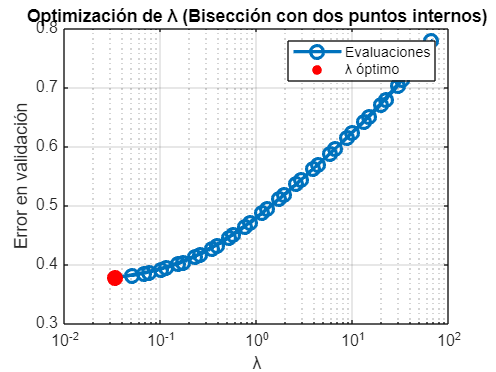


%% GRÁFICA 2: Bisección

figure;
semilogx(lambdas_eval, errores_eval, 'o-', 'LineWidth', 2, 'MarkerSize', 8);
hold on;
scatter(lambda_optimo, error_optimo, 100, 'r', 'filled');
xlabel('λ');
ylabel('Error en validación');
title('Optimización de λ (Bisección con dos puntos internos)');
legend('Evaluaciones', 'λ óptimo');
grid on;

saveas(gcf, 'figura2_biseccion.png');

fprintf('✓ Figura guardada: figura2_biseccion.png\n');

✓ Figura guardada: figura2_biseccion.png



%% --- función auxiliar para el error de validación ---
function err = calcular_error_validacion(X_tr, Y_tr, X_val, Y_val, lambda, tol_GS, max_iterGS)
    [beta, ~, ~] = gauss_seidel_ridge(X_tr, Y_tr, lambda, tol_GS, max_iterGS);
    Y_pred = X_val * beta;

    % Puedes elegir: RMSE o error relativo
    % RMSE:
    % err = sqrt(mean( (Y_val - Y_pred).^2 ));
    % Error relativo:
    err = norm(Y_val - Y_pred) / norm(Y_val);
end

%% COMPARACIÓN: GAUSS-SEIDEL VS MÉTODO DIRECTO (MEJORADO)
clear; clc;
load('datos_matrices.mat');

fprintf('=== COMPARACIÓN GS VS DIRECTO ===\n\n');

=== COMPARACIÓN GS VS DIRECTO ===




% Seleccionar características
correlaciones = zeros(size(X_train, 2), 1);
for i = 1:size(X_train, 2)
    correlaciones(i) = corr(X_train(:,i), Y_train);
end
[~, idx] = sort(abs(correlaciones), 'descend');

p = 100;
lambda = 1;
tol = 1e-4;

X_p = X_train(:, idx(1:p));
X_val_p = X_val(:, idx(1:p));
n = size(X_p, 1);

% Gauss-Seidel
[beta_GS, k, tiempo_GS] = gauss_seidel_ridge(X_p, Y_train, lambda, tol, 5000);
Y_pred_GS = X_val_p * beta_GS;

% Método Directo
A = X_p' * X_p + n * lambda * eye(p);
b = X_p' * Y_train;
tic;
beta_dir = A \ b;
tiempo_dir = toc;
Y_pred_dir = X_val_p * beta_dir;

% Resultados
error_rel = norm(beta_GS - beta_dir) / norm(beta_dir);

fprintf('Gauss-Seidel: %d iter, %.4fs\n', k, tiempo_GS);

Gauss-Seidel: 214 iter, 0.0039s


fprintf('Directo: %.4fs\n', tiempo_dir);

Directo: 0.0010s


fprintf('Error relativo: %.2e\n\n', error_rel);

Error relativo: 2.39e-03



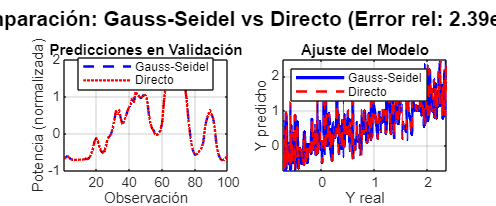


%% GRÁFICA MEJORADA: Dos versiones

figure('Position', [100, 100, 1200, 500]);

% VERSIÓN 1: Predicciones (solo métodos numéricos)
subplot(1,2,1);
plot(Y_pred_GS, 'b--', 'LineWidth', 1.5, 'DisplayName', 'Gauss-Seidel');
hold on;
plot(Y_pred_dir, 'r:', 'LineWidth', 1.5, 'DisplayName', 'Directo');
xlabel('Observación');
ylabel('Potencia (normalizada)');
title('Predicciones en Validación');
legend('Location', 'best');
grid on;
xlim([1 100]);  % Mostrar primeras 100 para claridad

% VERSIÓN 2: Ajuste del modelo (sin línea ideal)
subplot(1,2,2);
[Y_val_sorted, idx_sort] = sort(Y_val);
Y_GS_sorted  = Y_pred_GS(idx_sort);
Y_dir_sorted = Y_pred_dir(idx_sort);

plot(Y_val_sorted, Y_GS_sorted, 'b-', 'LineWidth', 2, 'DisplayName', 'Gauss-Seidel');
hold on;
plot(Y_val_sorted, Y_dir_sorted, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Directo');
xlabel('Y real');
ylabel('Y predicho');
title('Ajuste del Modelo');
legend('Location', 'northwest');
grid on;

sgtitle(sprintf('Comparación: Gauss-Seidel vs Directo (Error rel: %.2e)', error_rel), ...
        'FontSize', 13, 'FontWeight', 'bold');

saveas(gcf, 'figura3_comparacion_mejorada.png');

fprintf('✓ Figura guardada: figura3_comparacion_mejorada.png\n');

✓ Figura guardada: figura3_comparacion_mejorada.png
